clc, clear all, close all;

#### Checklist 

- Zkontrolovany zadane veliciny 

- **Zkontrolovany znamenka** u steiner + deviacnich momentu

- Znamenka Deviacni moment trojuhelnik


% zadane veliciny -- POZOR NA SPATNE ZADAVANI JEDNOTEK THO 
b = 26;
h = 13;

[obdelnik_big_JyT, obdelnik_big_JzT, obdelnik_big_JyTzT, obdelnik_big_S] = obdelnik(b,h);
%[obdelnik_small_JyT, obdelnik_small_JzT, obdelnik_small_JyTzT, obdelnik_small_S] = obdelnik(t2,h);
%[kruh_Jy,kruh_Jz,kruh_Jp,kruh_S] = kruh(D)
[tr_Jy,tr_Jz,tr_Jyz,tr_S] = trojuhelnik_k_tezisti(b,h);
%[tr_JyT,tr_JzT,tr_JyTzT,tr_S] = trojuhelnik_k_tezisti(b,h);

% posuvy pro steinerovu vetu
%x1 = (h-h1)/2 + h1;
%x2 = h1/2;

J_celk = ((obdelnik_big_JyTzT + (h/2)*(b/2)*obdelnik_big_S) + (tr_Jyz + (-b/3)*(h/3)*tr_S));
%J_celk = obdelnik_big_JzT + obdelnik_small_JzT;
J_celk = round(J_celk,0)

J_celk = 23801

#### Teorie

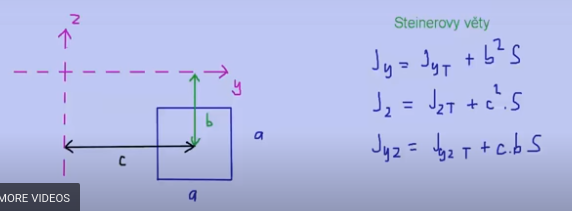

#### Vlastnosti kvadratickych momentu

- Jy, Jz (osove) musi byt vzdky kladne 

- Jyz (deviacni) muzou byt kladne, zaporne, nebo 0 

- Pokud je alespon jedna osa S.S. osou symetrie prurezu --> Deviacni == 0

- Celkovy moment prurezu je dan souctem dilcich momentu 

#### fce pro prurezy

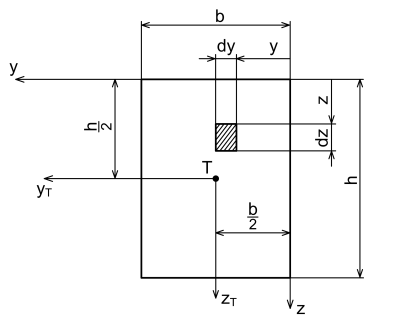

function [JyT,JzT,JyTzT,S] = obdelnik(b,h)
S = h*b;
JyT = (1/12)*b*(h^3);
JzT = (1/12)*(b^3)*h;
JyTzT = 0;
end

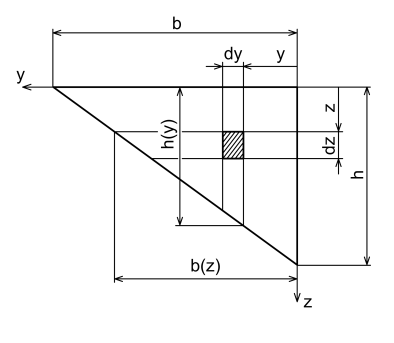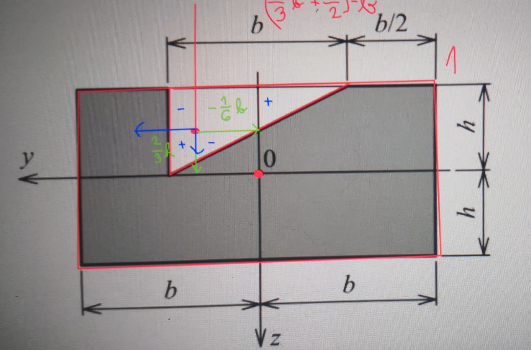

function [Jy,Jz,Jyz,S] = trojuhelnik(b,h)
% k osam vychazejicim od praveho uhla (obrazek)
S = (1/2)*b*h;
Jy = (1/12)*b*(h^3);
Jz = (1/12)*(b^3)*h;
Jyz = -(1/24)*(b^2)*(h^2);
end

function [JyT,JzT,JyTzT,S] = trojuhelnik_k_tezisti(b,h)
% k osam prochazejicim tezistem, bacha na znamenka deviacniho!!
S = (1/2)*b*h;
JyT = (1/36)*b*(h^3);
JzT = (1/36)*(b^3)*h;

% v pripade obrazku vlevo (-), vpravo (+) zalezi na orientaci os tho 
% orientaci os lokalniho volit podle orientace os centralniho SS 
JyTzT = +(1/72)*(b^2)*(h^2);
end

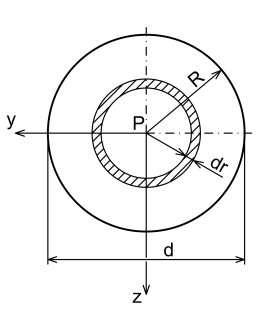

function [Jy,Jz,Jp,S] = kruh(d)
% k osam prochazejicim tezistem
S = (pi*d^2)/(4);
Jy = (1/64)*(pi*(d^4));
Jz = (1/64)*(pi*(d^4));
Jp = Jy + Jz;
end

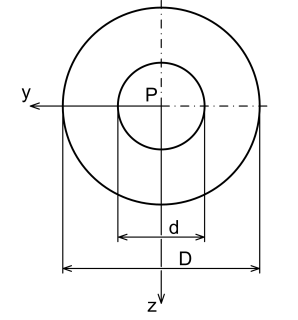

function [Jy,Jz,Jp,S] = mezikruzi(D,d)
% k osam prochazejicim tezistem
S = (pi*(D^2 - d^2))*(1/4);
Jy = (pi/64)*(D^4 - d^4);
Jz = Jy;
Jp = (pi/32)*(D^4 - d^4);
end